clc;
clear;

ssid = "TEST_BEACON";
beaconInterval = 100;
band = 2.4;
chNum = 6;

frameBodyConfig = wlanMACManagementConfig( ...
    BeaconInterval=beaconInterval, ...
    SSID=ssid);

dsElementID = 3;
dsInformation = dec2hex(chNum,2);
frameBodyConfig = frameBodyConfig.addIE(dsElementID,dsInformation);

beaconFrameConfig = wlanMACFrameConfig(FrameType="Beacon", ...
    ManagementConfig=frameBodyConfig);

[mpduBits,mpduLength] = wlanMACFrame(beaconFrameConfig,OutputFormat="bits");

fc = wlanChannelFrequency(chNum,band);

cfgNonHT = wlanNonHTConfig(PSDULength=61);

osf = 1;
tbtt = beaconInterval*1024e-6;
txWaveform = wlanWaveformGenerator(mpduBits,cfgNonHT,... 
    OversamplingFactor=osf,Idletime=tbtt);

Rs = wlanSampleRate(cfgNonHT,OversamplingFactor=osf);

txWaveform = [zeros(100, 1); txWaveform];

txWaveform = awgn(txWaveform * (-0.1 + 0.5i), 60);

## Packet Detection

rfRxFreq = 2.437e9; 

% rx = comm.SDRuReceiver( ...
%     'Platform',         'B210', ...
%     'SerialNum',        '344C4DE', ...
%     'MasterClockRate', 20e6, ...
%     'CenterFrequency',  rfRxFreq,...
%     'Gain', 30,...
%     'OutputDataType', 'double');

rxData = txWaveform;

detect the packet

startOffset1 = wlanPacketDetect(rxData, 'CBW20')

startOffset1 = 94

Calculate the LLTF index points

idxLLTF = wlanFieldIndices(cfgNonHT, 'L-LTF')

idxLLTF = 1×2 uint32 row vector
   161   320


Get non-HT fields

ind = wlanFieldIndices(cfgNonHT);
nonHTFields = rxData(startOffset1+(ind.LSTF(1):ind.LSIG(2)),:);

startOffset2 = wlanSymbolTimingEstimate(nonHTFields, "CBW20")

startOffset2 = 6

nonHTFields = rxData(startOffset1+startOffset2+(ind.LSTF(1):ind.LSIG(2)),:);

Demodulate the LLTF 

demodSig = wlanLLTFDemodulate(nonHTFields(idxLLTF(1):idxLLTF(2), :), cfgNonHT)

demodSig =   -0.1001 + 0.5000i  -0.1000 + 0.4989i
  -0.1000 + 0.5009i  -0.0991 + 0.5011i
   0.0995 - 0.4990i   0.1003 - 0.4991i
   0.0999 - 0.5002i   0.0999 - 0.4987i
  -0.0993 + 0.4999i  -0.1000 + 0.5003i
  -0.0997 + 0.4998i  -0.0995 + 0.5000i
   0.0993 - 0.4996i   0.0995 - 0.4991i
  -0.1005 + 0.5003i  -0.1002 + 0.5000i
   0.1005 - 0.5000i   0.0999 - 0.5001i
  -0.0987 + 0.5006i  -0.1004 + 0.4990i


Get channel estimation

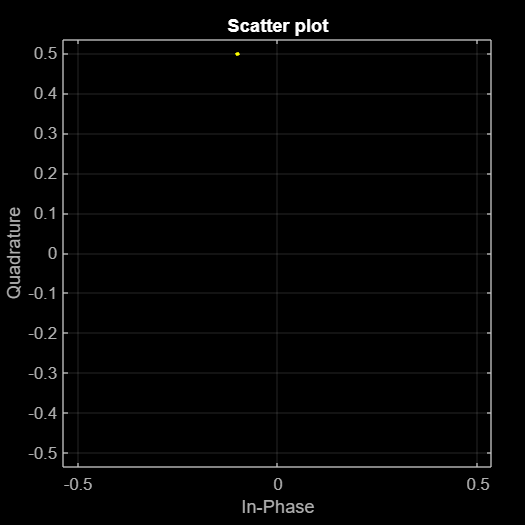

est = wlanLLTFChannelEstimate(demodSig, cfgNonHT);
scatterplot(est);
grid;